clear

% RRT:
KD_RRT_Star_Time  = [];
KD_iter           = [];
IsDebug           = false;

% Printing:
sampled_start_pts = [];
[printing_path_checkpoints, printing_progress] = Printing(2);
Obstacles                                      = Environment();

for ith_start = 1:1000 % number of starting points to grow RRT*
    [rand_start_pt, current_IRM] = Fake_sampleIRM(printing_path_checkpoints(1,:), printing_progress(1), IsDebug);
    sampled_start_pts            = [sampled_start_pts; rand_start_pt];
end

% if IsDebug
%     scatter(sampled_start_pts(:,1), sampled_start_pts(:,2),'filled', 'MarkerFaceColor', '#77AC30')
%     current_IRM_plot = fill(current_IRM(1,:), current_IRM(2,:), 'b', 'FaceAlpha', 0.2, 'EdgeColor',"none");
%     delete(current_IRM_plot);
% end

parfor idx = 1:length(sampled_start_pts(:,1))
    % Init:
    KDRRT                           = CLS_KDRRTStar;
    KDRRT.IsDEBUG                   = IsDebug;
    KDRRT.NN_method                 = 'KDTree_angle_diff_sq_norm';
    KDRRT.s_f                       = max(printing_progress);
    KDRRT.r_start                   = sampled_start_pts(idx,:);
    KDRRT.printing_path_checkpoints = printing_path_checkpoints;
    KDRRT.printing_progress         = printing_progress;
    
    % Build Obstacles:
%     [boundaries, n_obs_vertices, obs_vertices] = Obstacles(5);
%     hold on
    
    tic;
    [path, ite] = KDRRT.RRT_Star;
    time = toc;
    disp(['Trial ' + string(idx) + ' Found path in ' + string(ite) + ' iterations in ' + string(time) + ' secs.'])
    KD_iter          = [KD_iter, ite];
    KD_RRT_Star_Time = [KD_RRT_Star_Time, time];
end

Trial 27 Found path in 2710 iterations in 73.2876 secs.
Trial 1 Found path in 4028 iterations in 121.739 secs.
Trial 14 Found path in 3914 iterations in 130.7386 secs.
Trial 28 Found path in 2635 iterations in 64.018 secs.
Trial 29 Found path in 2533 iterations in 56.8217 secs.
Trial 2 Found path in 4197 iterations in 127.9989 secs.
Trial 3 Found path in 2916 iterations in 74.7324 secs.
Trial 15 Found path in 4713 iterations in 199.9688 secs.
Trial 30 Found path in 4080 iterations in 138.4899 secs.
Trial 40 Found path in 6761 iterations in 357.8044 secs.
Trial 31 Found path in 2941 iterations in 59.6298 secs.
Trial 41 Found path in 2104 iterations in 43.6371 secs.
Trial 16 Found path in 3717 iterations in 128.7445 secs.
Trial 32 Found path in 2917 iterations in 69.9764 secs.
Trial 4 Found path in 4698 iterations in 152.9946 secs.
Trial 5 Found path in 2278 iterations in 44.7108 secs.
Trial 42 Found path in 4646 iterations in 176.5461 secs.
Trial 43 Found path in 2364 iterations in 55.9

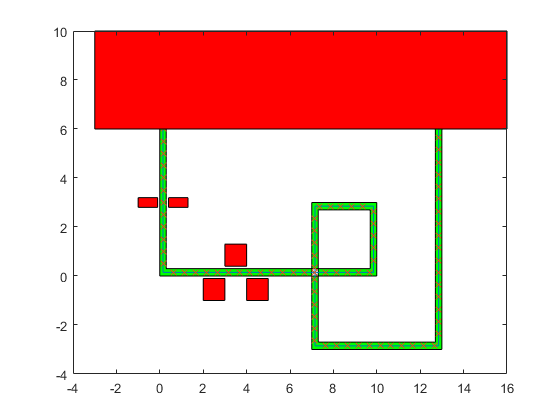

hold off

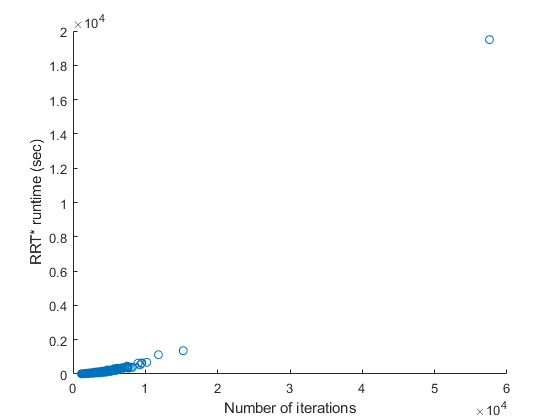

scatter(KD_iter, KD_RRT_Star_Time)
xlabel('Number of iterations')
ylabel('RRT* runtime (sec)')